# The sharpness of combination fingerings

Why do combination fingerings (12, 23, 13, and 123) tend to be sharp? How sharp are they? And are they all the same?

## F horn

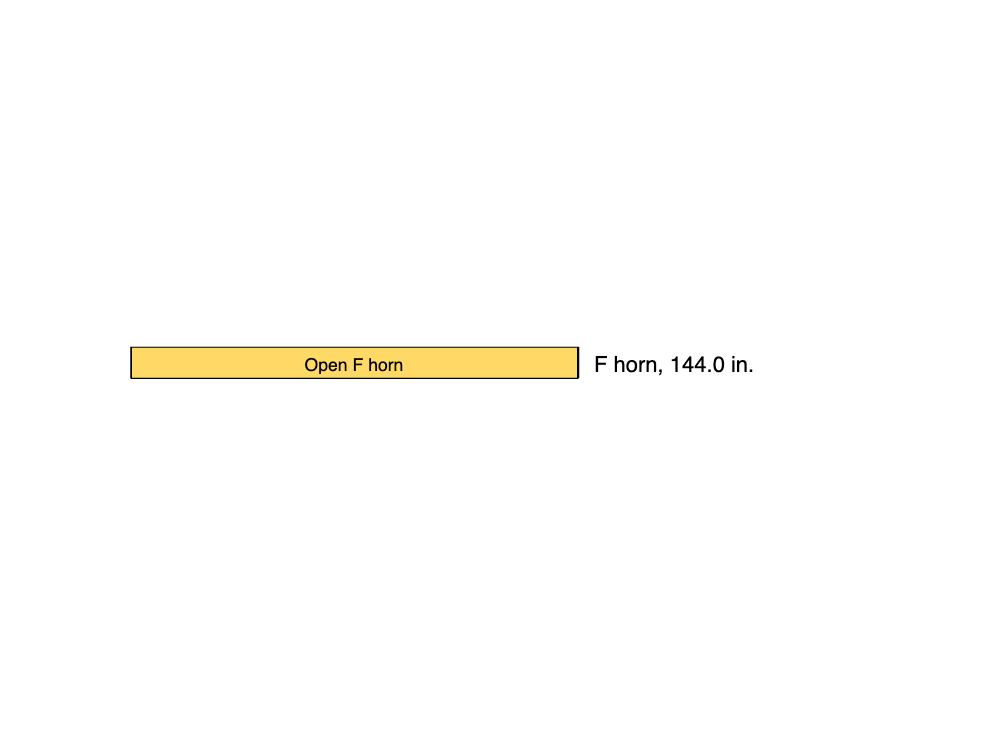

close all
f_horn_length = 144;
f_horn_sections = {0 144 "Open F horn"};
ax = newplot;
plotHorn(ax,f_horn_length,"F horn",0,f_horn_sections)

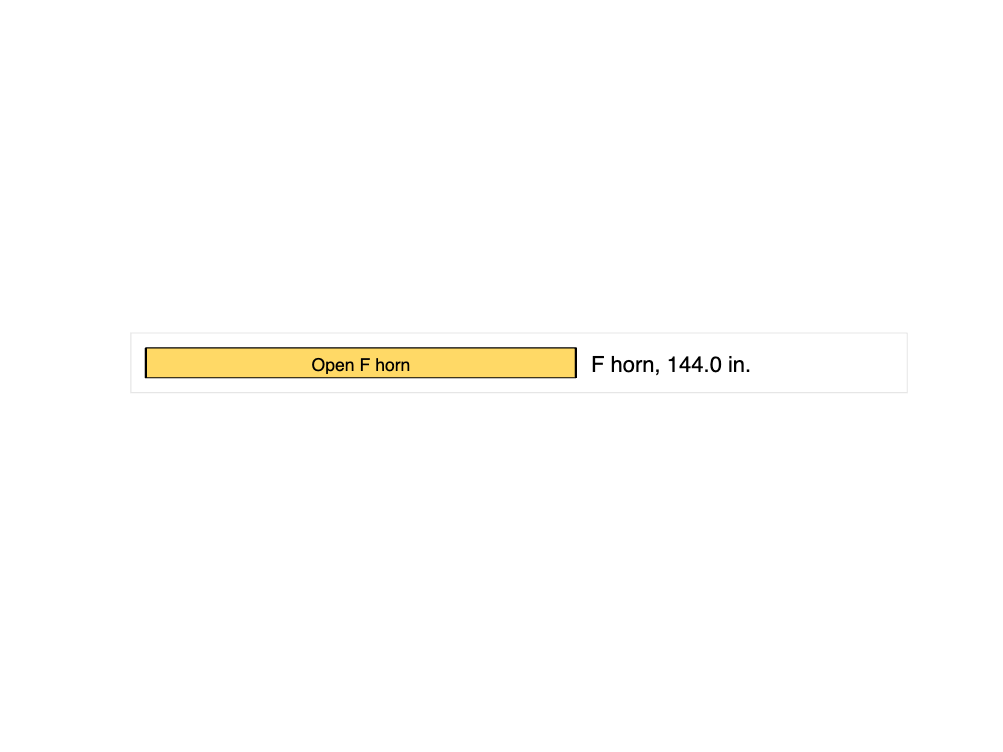

exportHornDiagram(ax,"f-horn.png")

## The E horn and valve slide 2

To lower the F horn's pitch by a half step, making it an E horn, you have to lengthen it by approximately 5.95%, or about 8.6 in. The exact percentage is:


$$\left(2^{1/12} -1\right)\times 100%$$


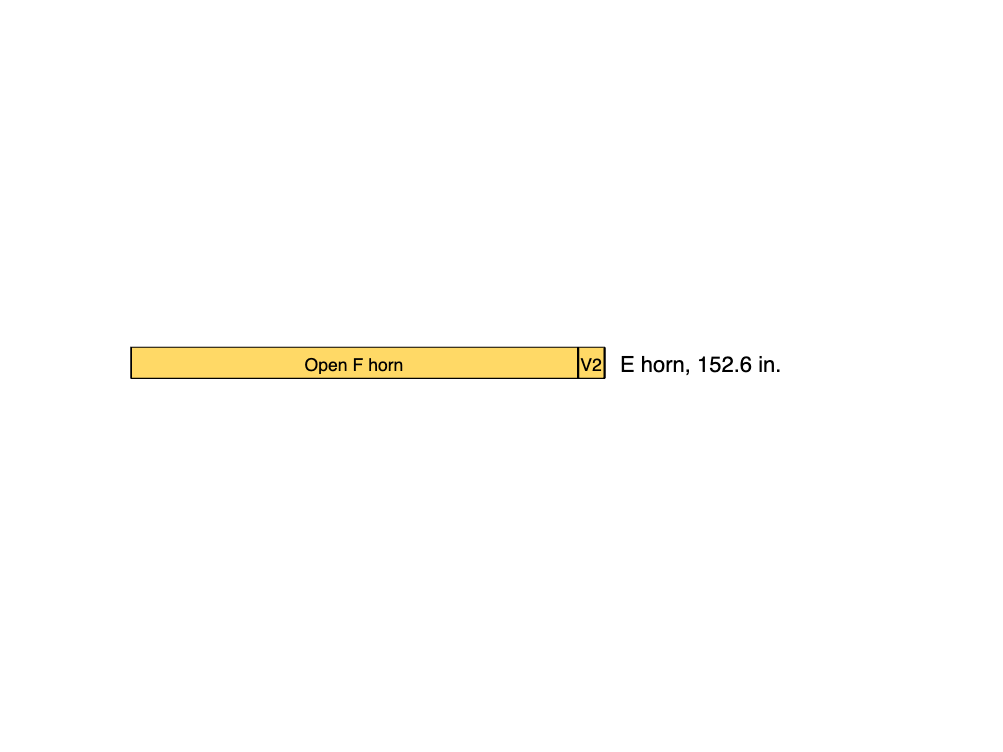

s = 2^(1/12);
e_horn_length = f_horn_length * s;
e_horn_label = "E horn";
v2 = e_horn_length - f_horn_length;
e_horn_sections = { ...
    0             f_horn_length    "Open F horn"
    f_horn_length f_horn_length+v2 "V2"    };
ax = newplot;
plotHorn(ax,e_horn_length,"E horn",0,e_horn_sections);

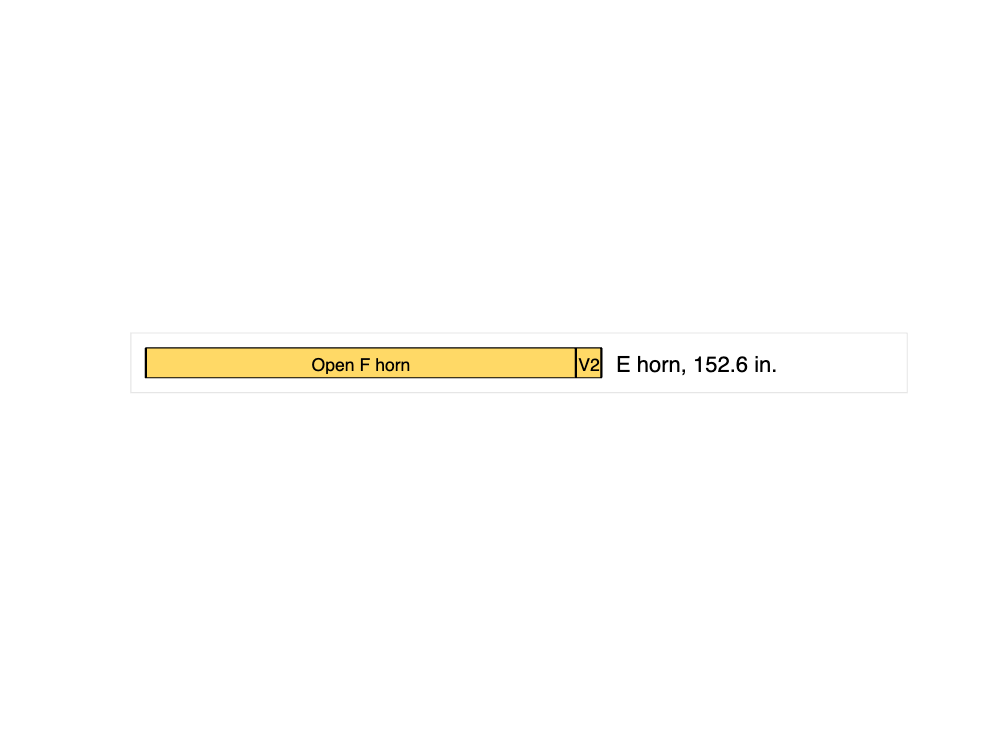

exportHornDiagram(ax,"e-horn.png")

## The E♭ horn and valve slide 1

To lower the F horn's pitch by a whole step, making it an E♭ horn, you have to lengthen it by approximately 12.2%, or about 17.6 in. The exact percentage is:


$$\left(2^{2/12} -1\right)\times 100%$$


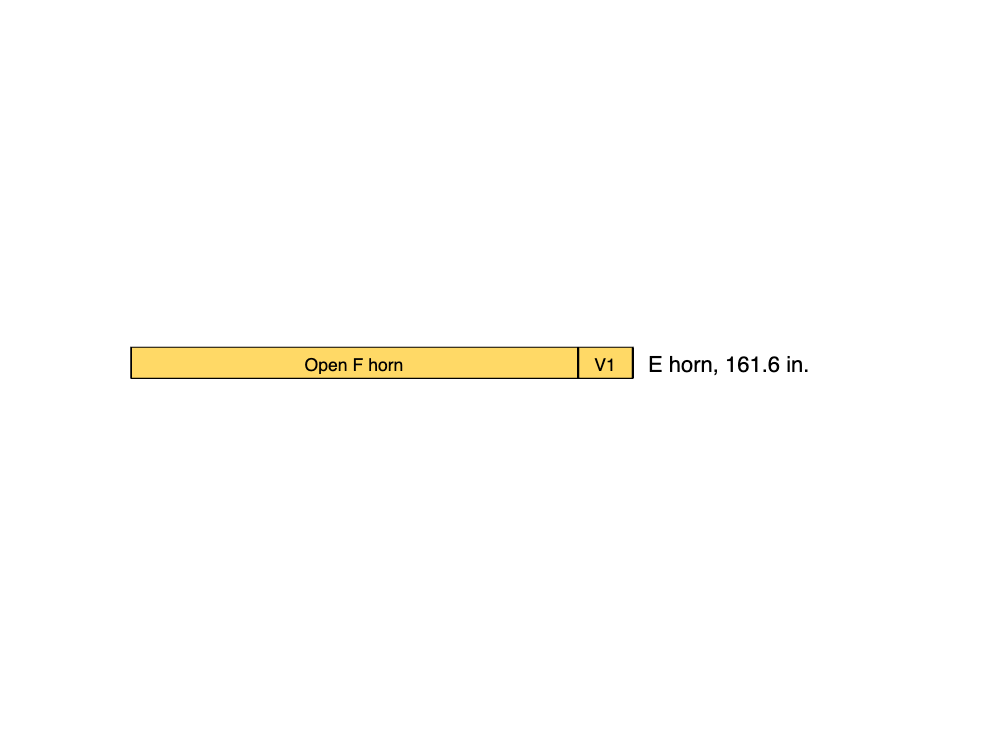

s = 2^(2/12);
e_flat_horn_length = f_horn_length * s;
e_flat_horn_label = "E♭ horn";
v1_length = e_flat_horn_length - f_horn_length;
e_flat_horn_sections = { ...
    0             f_horn_length           "Open F horn"
    f_horn_length f_horn_length+v1_length "V1"      };
ax = newplot;
plotHorn(ax,e_flat_horn_length,"E horn",0,e_flat_horn_sections);

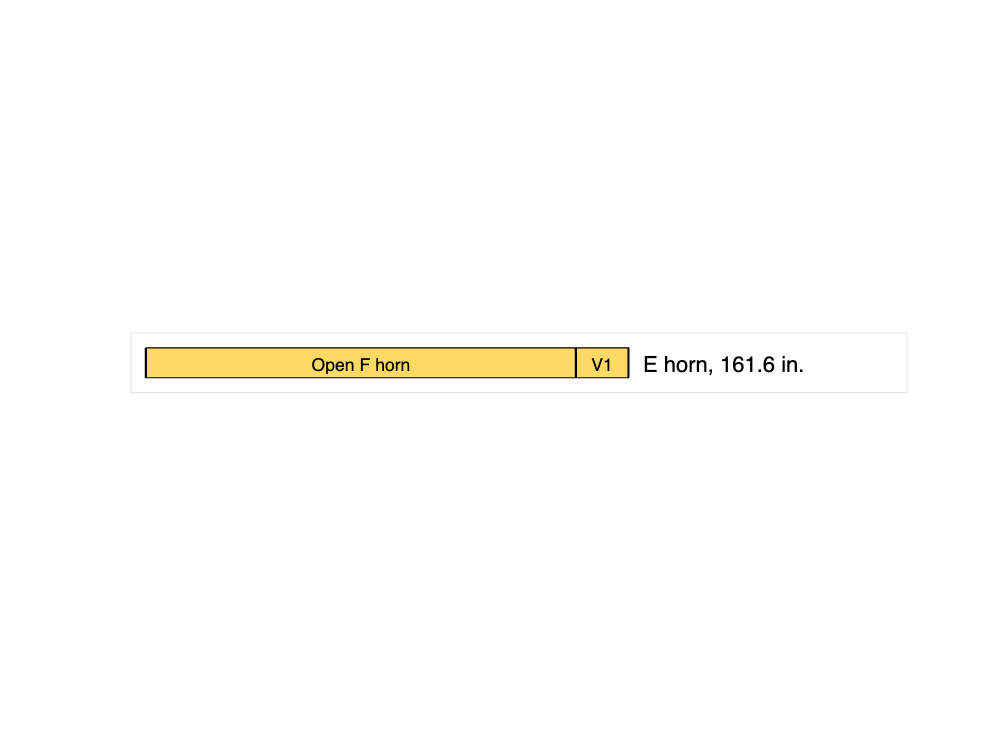

exportHornDiagram(ax,"e-flat-horn.png")

## The D horn and fingering F12

To lower the F horn's pitch by a three half steps, making it a D horn, you have to lengthen it by approximately 18.9%, or about 27.2 in. The exact percentage is:


$$\left(2^{3/12} -1\right)\times 100%$$


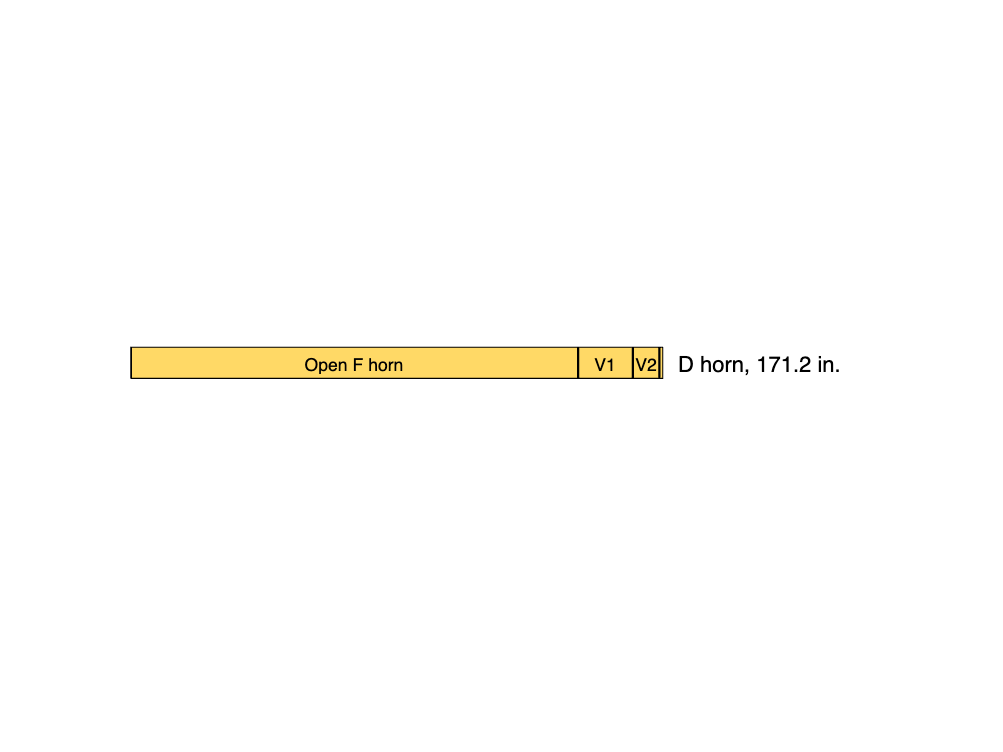

s = 2^(3/12);
d_horn_length = f_horn_length * s;
d_horn_label = "D horn";
v1 = e_flat_horn_length - f_horn_length;
v2 = e_horn_length - f_horn_length;
d_horn_sections = { ...
    0 f_horn_length "Open F horn"
    f_horn_length f_horn_length+v1_length "V1"
    f_horn_length+v1 f_horn_length+v1+v2 "V2" };
ax = newplot;
plotHorn(ax,d_horn_length,"D horn",0,d_horn_sections)

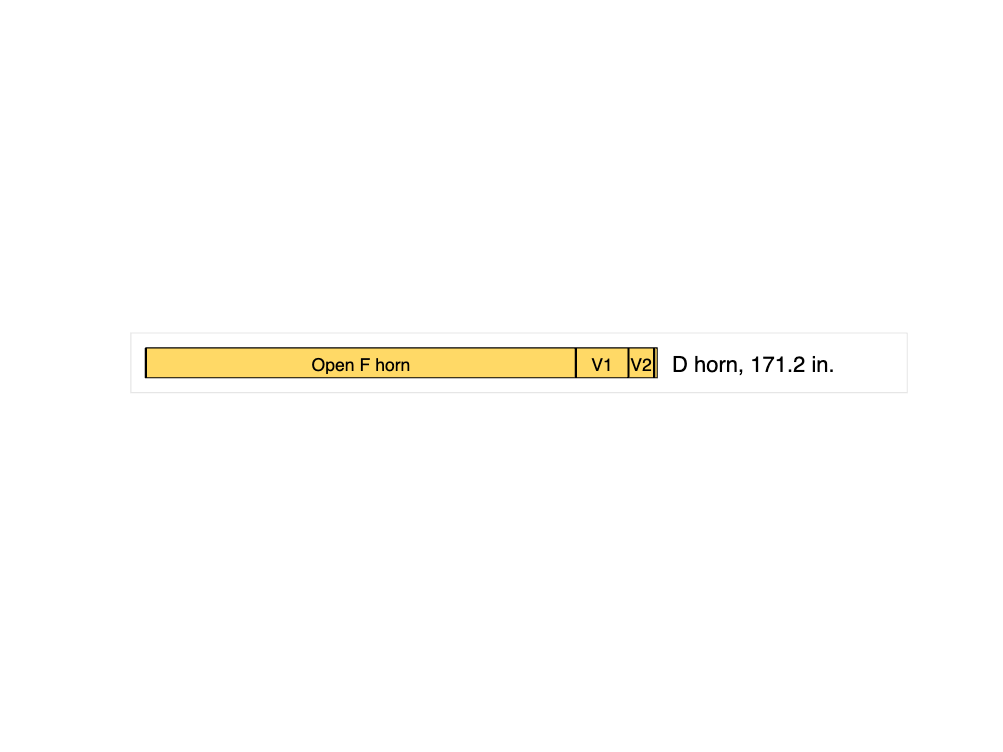

exportHornDiagram(ax,"d-horn.png")

If valve slide 1 is 17.6 in. (to lower the F horn by exactly a whole step), and valve slide 2 is 8.6 in., then using both slides lengthens the F horn by 17.6 in. + 8.6 in., or 26.2 in. That is about an inch shorter than it should be to lower the F horn by a full three half steps. That 1 in. difference is enough to make the F12 fingering about 11 cents sharp compared to the ideal D horn.

## The B horn and fingering F123

To lower the F horn's pitch by six half steps, making it a B horn, you have to lengthen it by approximately 41.4%, or about 59.6 in. (almost 5 feet!) The exact percentage is:


$$\left(2^{6/12} -1\right)\times 100%$$


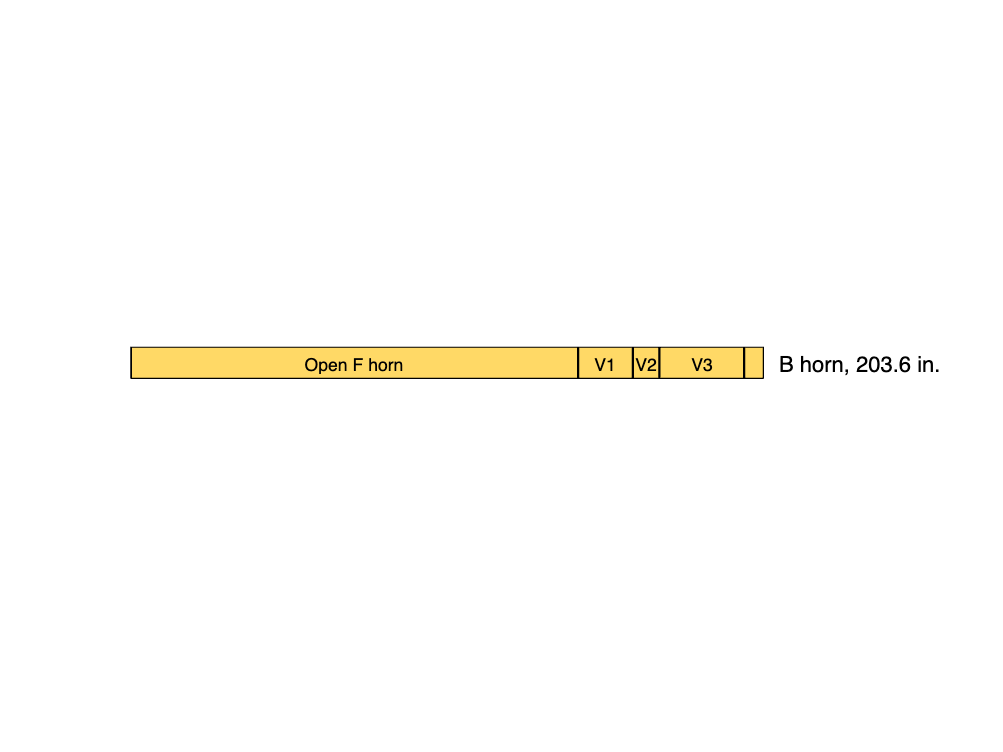

s = 2^(6/12);
b_horn_length = f_horn_length * s;
b_horn_label = "B horn";
v3 = (2^(3/12) - 1) * f_horn_length;
b_horn_sections = { ...
    0 f_horn_length "Open F horn"
    f_horn_length f_horn_length+v1_length "V1"
    f_horn_length+v1 f_horn_length+v1+v2 "V2" 
    f_horn_length+v1+v2 f_horn_length+v1+v2+v3 "V3"};
ax = newplot;
plotHorn(ax,b_horn_length,"B horn",0,b_horn_sections)

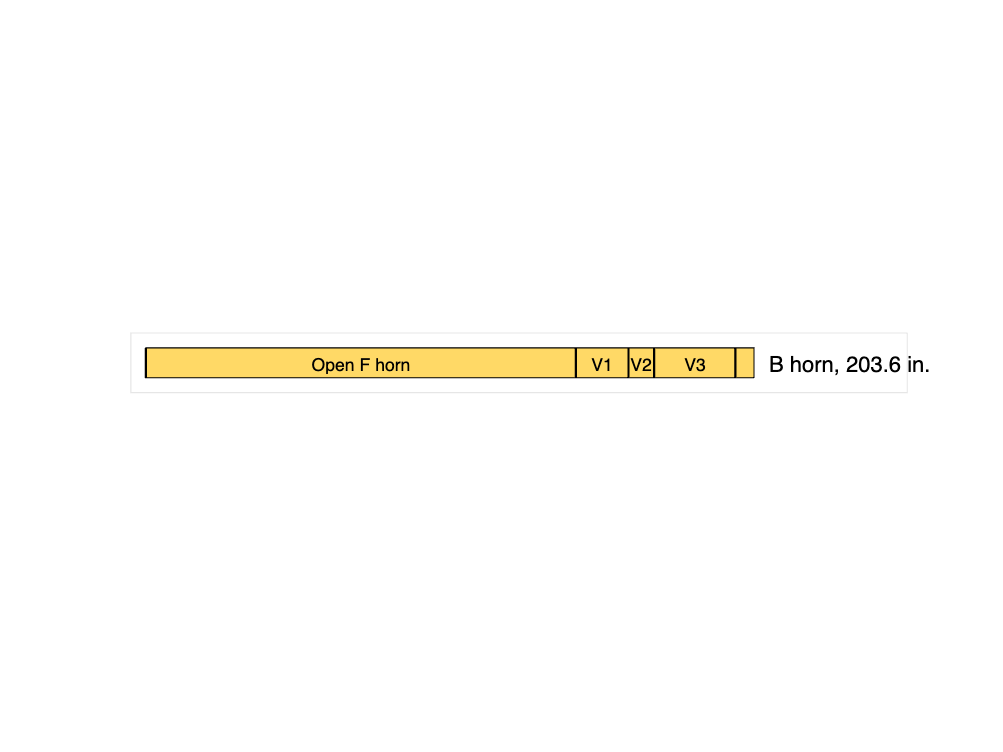

exportHornDiagram(ax,"b-horn.png")

The discrepancy between the B horn and the length of the F123 combination is a bit more than 6 inches:

b_horn_length - f_horn_length - v1 - v2 - v3

ans = 6.2037

This makes the F123 combination about 54 cents sharp.

## Show all the horns together

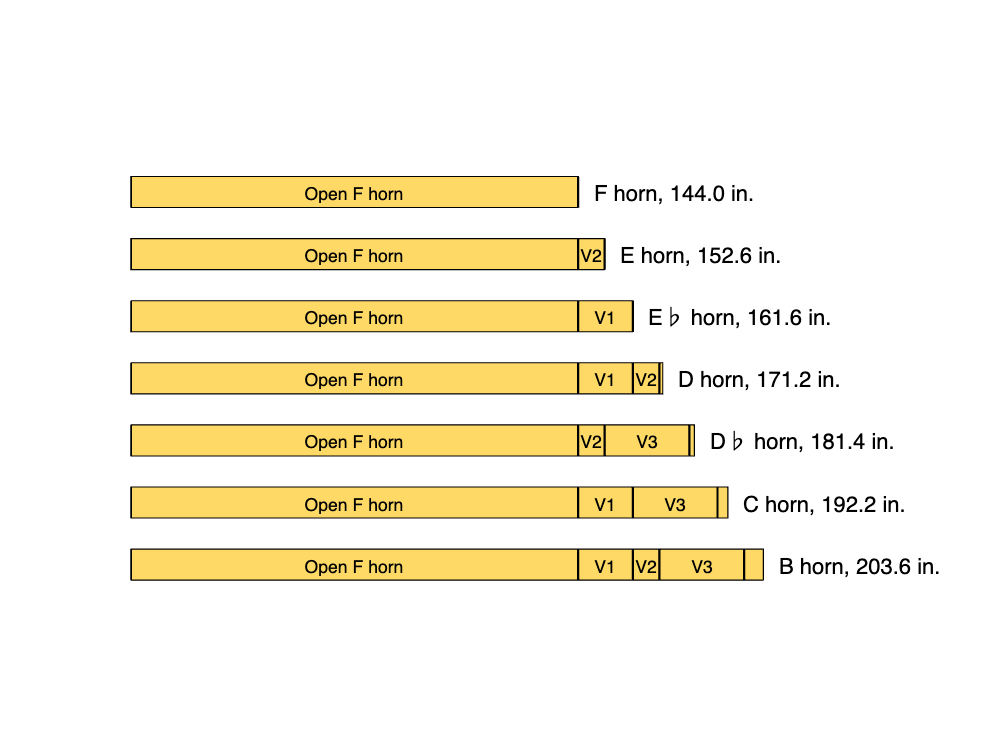

d_flat_horn_length = 144 * 2^(4/12);
d_flat_horn_sections = { ...
    0 f_horn_length "Open F horn"
    f_horn_length f_horn_length+v2 "V2"
    f_horn_length+v2 f_horn_length+v2+v3 "V3"};

c_horn_length = 144 * 2^(5/12);
c_horn_sections = { ...
    0 f_horn_length "Open F horn"
    f_horn_length f_horn_length+v1_length "V1"
    f_horn_length+v1 f_horn_length+v1+v3 "V3"};

ax = newplot;
plotHorn(ax,f_horn_length,"F horn",0,f_horn_sections);
hold on
plotHorn(ax,e_horn_length,"E horn",20,e_horn_sections);
plotHorn(ax,e_flat_horn_length,"E♭ horn",40,e_flat_horn_sections);
plotHorn(ax,d_horn_length,"D horn",60,d_horn_sections);
plotHorn(ax,d_flat_horn_length,"D♭ horn",80,d_flat_horn_sections);
plotHorn(ax,c_horn_length,"C horn",100,c_horn_sections);
plotHorn(ax,b_horn_length,"B horn",120,b_horn_sections);
hold off

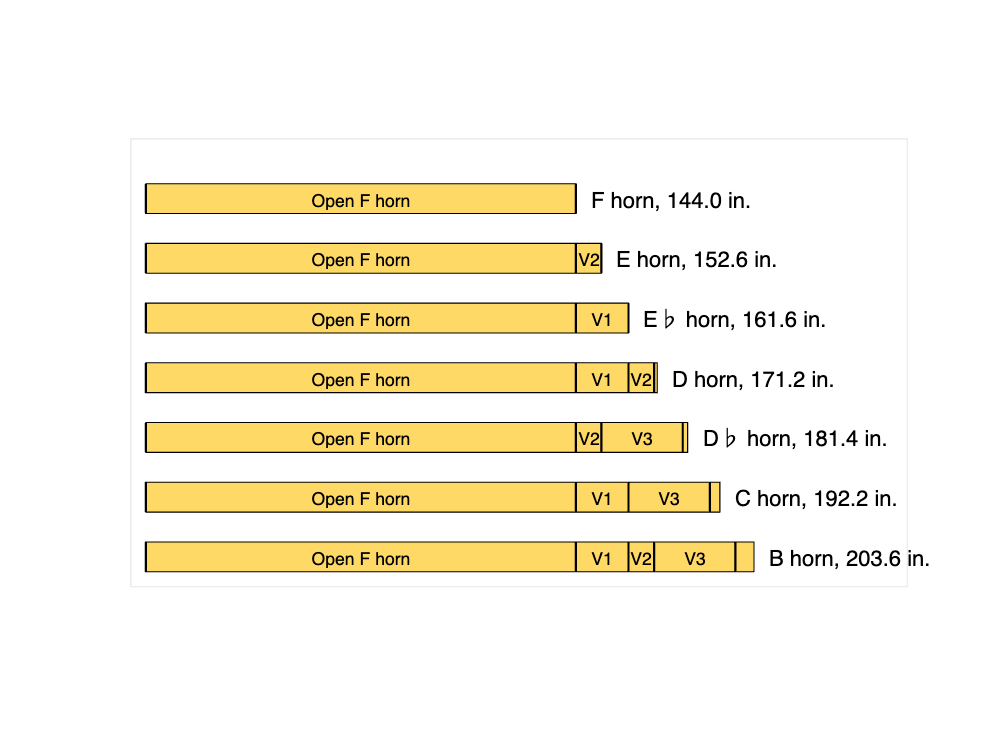

exportHornDiagram(ax,"all-horns.png")

## Pitch differences

freq_d = 1/d_horn_length;
freq_12 = 1/(f_horn_length + v1 + v2);
F12_intonation = pitchDelta(freq_d,freq_12)

F12_intonation = 11

freq_d_flat = 1/d_flat_horn_length;
freq_23 = 1/(f_horn_length + v2 + v3);
F23_intonation = pitchDelta(freq_d_flat,freq_23)

F23_intonation = 16

freq_c = 1/c_horn_length;
freq_13 = 1/(f_horn_length + v1 + v3);
F13_intonation = pitchDelta(freq_c,freq_13)

F13_intonation = 30

freq_b = 1/b_horn_length;
freq_123 = 1/(f_horn_length + v1 + v2 + v3);
F123_intonation = pitchDelta(freq_b,freq_123)

F123_intonation = 54

## Helper functions

function plotHorn(ax, L, label, y_offset, sections)
    if nargin < 5
        sections = cell(0,3);
    end
    if nargin < 4
        y_offset = 0;
    end
    w = 10;
    y1 = 0;
    y2 = w;
    yy = [y1 y1 y2 y2 y1];
    horn_color = [255 217 102]/255;

    x1 = 0;
    x2 = L;
    xx = [x1 x2 x2 x1 x1];
    patch(ax,xx,yy - y_offset,horn_color)
    full_label = sprintf("%s, %.1f in.",label,x2);
    text(x2 + 5,w/2 - y_offset,full_label, ...
        VerticalAlignment = "middle")


    for k = 1:size(sections,1)
        vx1 = sections{k,1};
        vx2 = sections{k,2};
        vyy = [0 w] - y_offset;

        line(ax,[vx1 vx1],vyy, LineWidth = 1, Color = "black");
        line(ax,[vx2 vx2],vyy, LineWidth = 1, Color = "black");

        text(mean([vx1 vx2]),mean(vyy),sections{k,3},...
            HorizontalAlignment = "center", ...
            VerticalAlignment = "middle",...
            FontSize = 8);
    end

    daspect(ax,[1 1 1])
    axis(ax,"off")
    ax.XLim = [0 250];
end

function cents = pitchDelta(F1,F2)
    cents = round(1200 * log2(F2/F1));
end

function exportHornDiagram(ax,filename)
    ax.XLim = ax.XLim + [-5 5];
    ax.YLim = ax.YLim + [-5 5];
    ax.XTick = [];
    ax.YTick = [];
    ax.XColor = [.9 .9 .9];
    ax.YColor = [.9 .9 .9];
    axis(ax,"on")
    box(ax,"on")
    exportgraphics(ax,filename,Resolution = 300)
end